clearvars
close all
clc
load("MS_973_A_2.mat");
lat = Position.latitude;
lon = Position.longitude;
speed = Position.speed;

basemapName = "offlineBusMap";
mbtilesFile = "osm-2020-02-10-v3.11_italy_milan.mbtiles";

addCustomBasemap(basemapName, mbtilesFile)

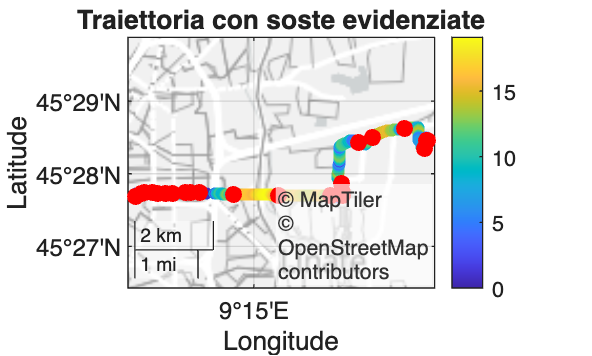

speed_f = movmean(speed, 5);
isStopped = speed_f < 1.0;   % soglia più realistica


isStopped = speed_f < 0.5;

figure;
geobasemap offlineBusMap

geoscatter(lat(~isStopped), lon(~isStopped), 20, speed(~isStopped), 'filled')
hold on
geoscatter(lat(isStopped), lon(isStopped), 40, 'red', 'filled')

colorbar
title('Traiettoria con soste evidenziate')